
cal_ci = 1;
sigma = 20;
dt = 1;

i = 36;
spktimes = spikeInfo.SpikeTimes{i};
beh_info = behavInfo(behavInfo.Session==spikeInfo.Session(i) & behavInfo.Subject==spikeInfo.Subject(i), :);

%% Task information
FP = unique(beh_info.FP(beh_info.Stage==1));
if length(FP)>1
    FP = mode(FP);
end
NumFPs = length(FP);

Ports = unique(beh_info.PortCorrect);
NumPorts = length(Ports);

%% Gather all
SDFAll = SpikesGPS.ComputeSDFAllLite(spktimes, beh_info, sigma, dt);

win_post = 1.0e+03 *

    5.2971
    5.2079
    5.1877
    5.1132
    5.1607
    5.5986
    5.2030
    5.0686
    5.1607
    5.4499


% for i = 1:length(SDFAll.sdf)
%     [SDFAll.sdf{i}, SDFAll.t_sdf{i}] = downsample_sdf(SDFAll.sdf{i}, SDFAll.t_sdf{i}, dt);
% end
SDFTable = struct2table(SDFAll);


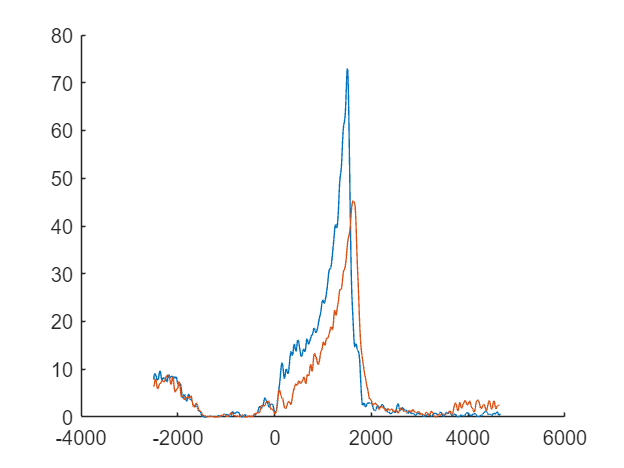

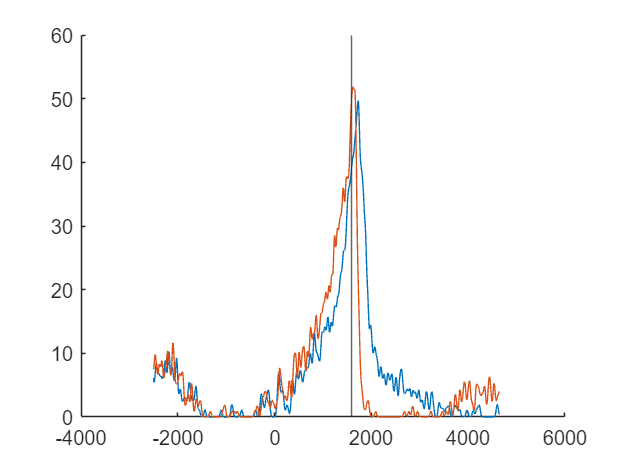

%% Warp sdf for each condition
% warp correct trials only
SDFUncue = SDFTable(SDFAll.Cued==0, :);

% the whole duration of time warp
pre_  = 2.5; % 2.5 sec before cent-in, about the lower boundary of shuttle time
post_ = 3; % take 3 sec after choice at first
post_keep = 2.5; % should be shorter than post_, to avoid length error

latency = 2.5; % max cent-out to choice latency (max movement time)

% trim whole trial sdf to time warp duration
% remove trials with long movement time
ind_invalid = SDFUncue.MT>=latency*1000 & SDFUncue.HD<=200;
SDFUncue = SDFUncue(~ind_invalid, :);
% remove trials with outlier HD
[~, ind_out] = rmoutliers(SDFUncue.HD);
SDFUncue = SDFUncue(~ind_out, :);

% trial_dur = num2cell(SDFUncue.t_choice - SDFUncue.t_centin);
SDFUncue.sdf = cellfun(@(x,t) x(t>=-pre_*1000), SDFUncue.sdf, SDFUncue.t_sdf, 'UniformOutput', false);
SDFUncue.t_sdf = cellfun(@(t) t(t>=-pre_*1000), SDFUncue.t_sdf, 'UniformOutput', false);

%% Warp for each condition
n_valid = height(SDFUncue);
SDFUncue.t_point  = cell(n_valid, 1);
SDFUncue.t_warp   = cell(n_valid, 1);
SDFUncue.sdf_warp = cell(n_valid, 1);

t_points = cell(1, NumPorts);
sdf_warp = cell(1, NumPorts);
t_warped = cell(1, NumPorts);
for j = 1:NumPorts
    j_port = Ports(j);

    ind_j = find(SDFUncue.Port==j_port);
    if isempty(ind_j)
        continue
    end

    SDF_j = SDFUncue(ind_j, :);
    median_hold_duration = median(SDF_j.HD, 'omitnan'); % median, in ms
    median_movement_time = median(SDF_j.MT(SDF_j.Outcome=="Correct"), 'omitnan'); % median, in ms
    % cent-in, trigger, cent-out, choice (relative to cent-in moment)
    t_points{j} = [0 median_hold_duration median_hold_duration+median_movement_time];
    t_temp = [-pre_*1000 t_points{j} t_points{j}(end)+post_keep*1000];

    t_target = t_temp(1)+dt/2:dt:t_temp(end)-dt/2;
    sdf_warp{j} = nan(length(ind_j), length(t_target));
    for k = 1:length(ind_j) % for each trial
        switch SDF_j.Outcome(k)
            case 'Correct'
                % take the full time templates
                k_t_temp = t_temp;
                % time points in this trial normalize so that the first point is time 0
                k_t_point = [SDF_j.t_centin(k) SDF_j.t_centout(k) SDF_j.t_choice(k)] - SDF_j.t_centin(k);
                k_t_point = [-pre_*1000 k_t_point k_t_point(end)+post_keep*1000];
            otherwise
                % remove t_choice
                k_t_temp = t_temp;
                k_t_temp(end-1) = [];
                % time points in this trial normalize so that the first point is time 0
                k_t_point = [SDF_j.t_centin(k) SDF_j.t_centout(k)] - SDF_j.t_centin(k);
                k_t_point = [-pre_*1000 k_t_point k_t_point(end)+median_movement_time+post_keep*1000];
        end

        k_t_sdf = SDF_j.t_sdf{k}; % in ms
        k_sdf   = SDF_j.sdf{k}; % this is the sdf

        k_sdf_warp = cell(1, length(k_t_temp)-1);
        for m = 1:length(k_t_temp)-1
            m_t_temp = k_t_temp([m m+1]);
            m_t_warp = t_target(t_target>=m_t_temp(1) & t_target<m_t_temp(2));

            m_t_point = k_t_point([m m+1]);
            m_sdf     = k_sdf(k_t_sdf>=m_t_point(1) & k_t_sdf<m_t_point(2));
            m_t_sdf   = k_t_sdf(k_t_sdf>=m_t_point(1) & k_t_sdf<m_t_point(2));

            m_sdf_warp = warp_sdf(m_t_sdf, m_sdf, m_t_warp);

            k_sdf_warp{m} = m_sdf_warp;
        end
        sdf_warp{j}(k,:) = cat(2, k_sdf_warp{:});

        SDFUncue.t_point{ind_j(k)}  = t_points{j};
        SDFUncue.t_warp{ind_j(k)}   = t_target;
        SDFUncue.sdf_warp{ind_j(k)} = cat(2, k_sdf_warp{:});
    end
    t_warped{j} = t_target;
end

% Calculate mean and CI of warped sdf
sdf_warped_ci = cell(1, NumPorts);
sdf_warped_m  = cell(1, NumPorts);
for j = 1:NumPorts
    sdf_warped_m{j} = mean(sdf_warp{j}, 1);
    if cal_ci
        if size(sdf_warp{j}, 1)>=5
            sdf_warped_ci{j} = bootci(1000, @mean, sdf_warp{j});
        else
            sdf_warped_ci{j} = nan(2, length(sdf_warped_m{j}));
        end
    end
end

SDFWarp.t_points = t_points;
SDFWarp.t_points_description = ["CentIn", "CentOut", "Choice"];
SDFWarp.pre_post_durations = [pre_, post_, post_keep];

SDFWarp.t_warp   = t_warped;
SDFWarp.sdf_warp = sdf_warp;
SDFWarp.sdf_mean = sdf_warped_m;
SDFWarp.sdf_ci   = sdf_warped_ci;


%% Save sdf of correct trials
SDFAll.SDFCorrect = SDFUncue;
SDFAll.SDFWarp = SDFWarp;
